# Simple cells

Simple cells in V1 respond to bars of light at specific orientations and scales. One way to model these cells is with a Gabor function. 

## Build Gabor function

clear all; clc;

#### Initialize two parameters, OR and SF.

By varying OR and SF, construct simple cells sensitive to different orientations and spatial frequencies.

%% 2a Define values
OR = 0; %orientation in radians
SF = 0.01;  %spatial frequency

#### Perform a 2D coordinate rotation transformation.

The original *(x,y)* coordinate system is rotated counterclockwise around the origin by an angle *θ*, resulting in new coordinates *(X,Y)*.

x = -20:1:20;
[x, y] = meshgrid(x);
X=x*cos(OR) + y*sin(OR);
Y=-x*sin(OR) + y*cos(OR);

#### Construct the Gabor function

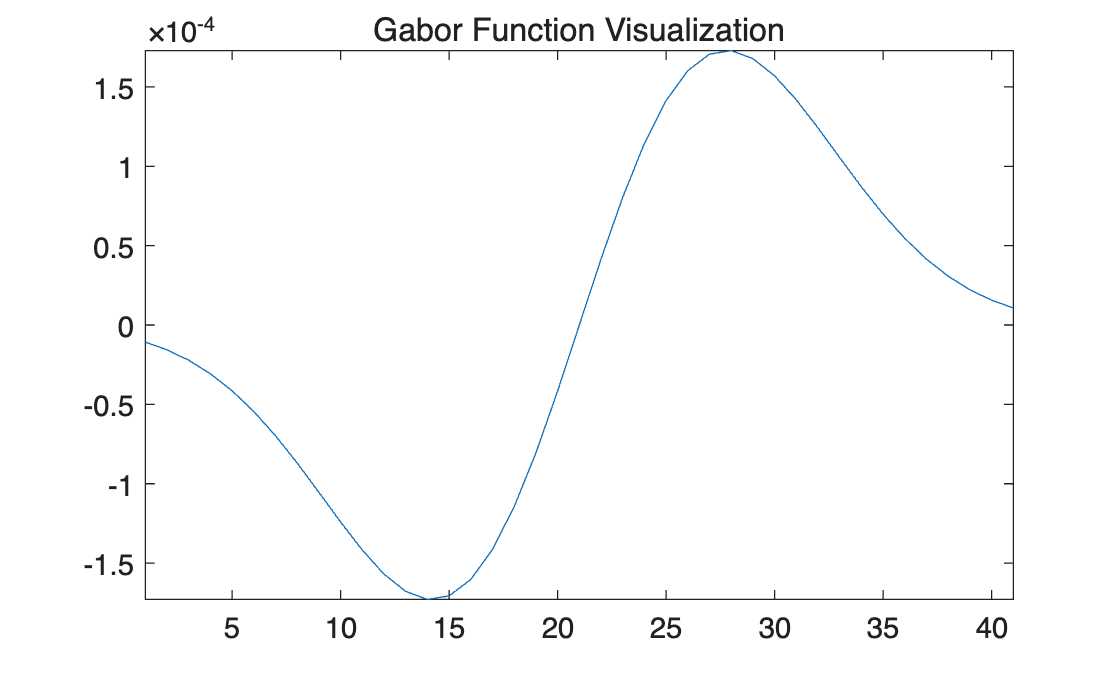

sigma_x = 7; % standard deviation in x-direction
sigma_y = 17; % standard deviation in y-direction

gaussian_2d = 1/(2*pi*sigma_x*sigma_y) * exp(-(X.^2/(2*sigma_x^2)+Y.^2/(2*sigma_y^2)));
A = sin(2*pi*SF*X);
Gabor_function = A .* gaussian_2d;

%plot figure
figure;
plot(Gabor_function(1,:));
axis tight;
title('Gabor Function Visualization');

## convolve image with Gabor function

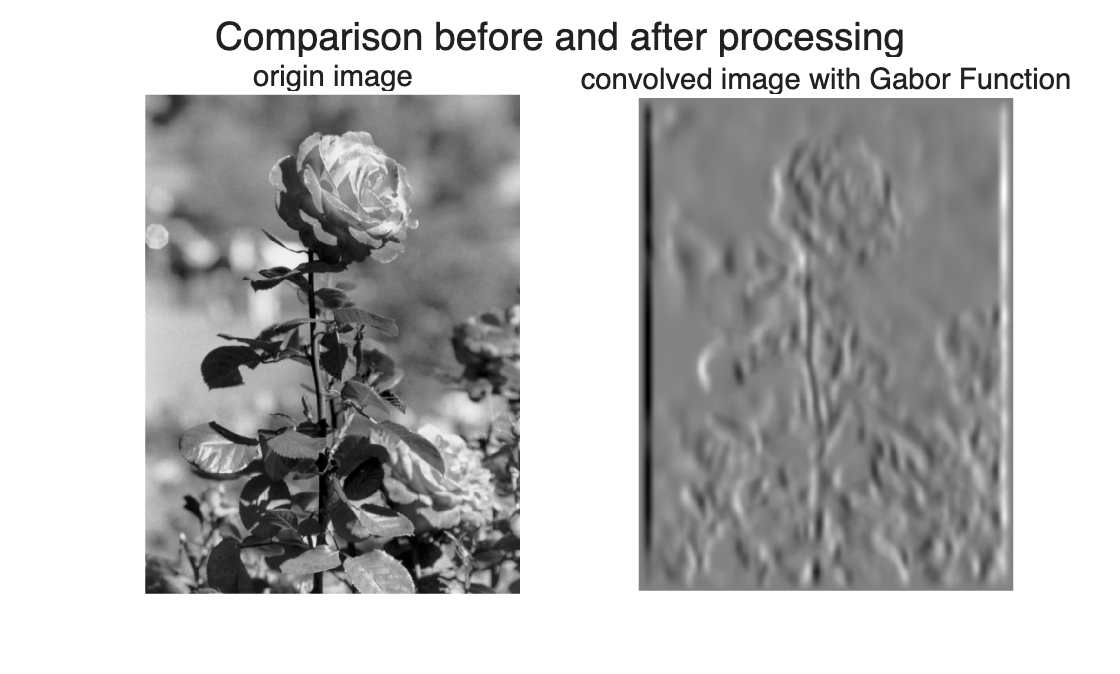

img = imread('rose.jpg');
img_conv = conv2(img, Gabor_function);

% Display the convolved image
figure;
subplot(1,2,1)
imshow(img)
title('origin image')
subplot(1,2,2)
imagesc(img_conv);
colormap(gray);
axis image;
axis off;
title('convolved image with Gabor Function');
sgtitle('Comparison before and after processing');

## Change the parameter OR

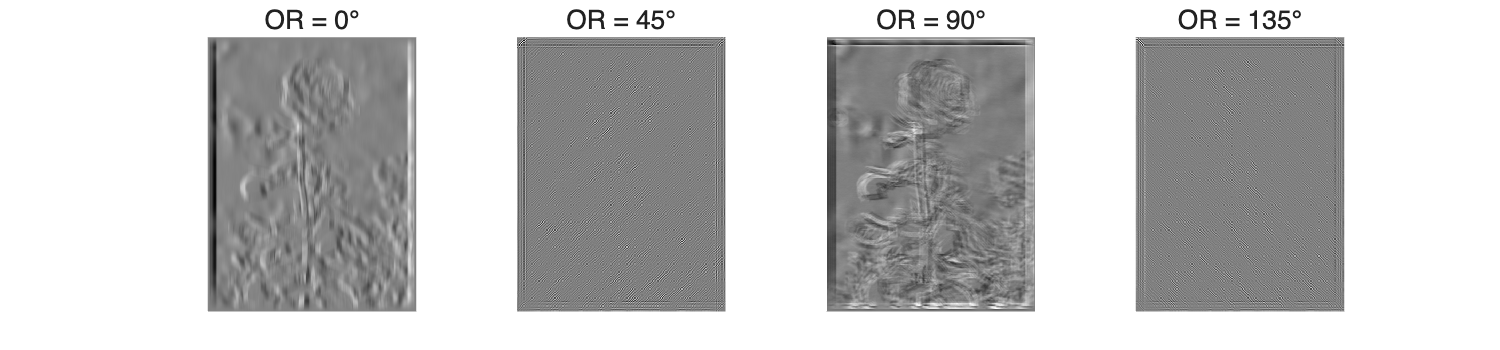

img = imread('rose.jpg');
SF = 0.5;
ORs = [0, pi/4, pi/2, 3*pi/4];
titles = {'0°', '45°', '90°', '135°'};
figure('Position', [100, 100, 1500, 350]);
for i = 1:4
    OR = ORs(i);
    X = x*cos(OR) + y*sin(OR);
    Y = -x*sin(OR) + y*cos(OR);

    gaussian_2d = 1/(2*pi*sigma_x*sigma_y) * exp(-(X.^2/(2*sigma_x^2)+Y.^2/(2*sigma_y^2)));
    A = sin(2*pi*SF*X);

    Gabor_function = A .* gaussian_2d;

    img_conv = conv2(img, Gabor_function);
    subplot(1,4,i)
    imagesc(img_conv);
    colormap(gray);
    axis image;
    axis off;
    title(['OR = ' titles{i}]);
end

It can be observed that this image contains more details at the 90° orientation. The results demonstrated that distinct orientations isolate specific directional textures.

Among the cells with higher spatial frequency (i.e., those sensitive to finer details), only the cells selective for the 90° orientation extract more information.

## Change the parameter SF

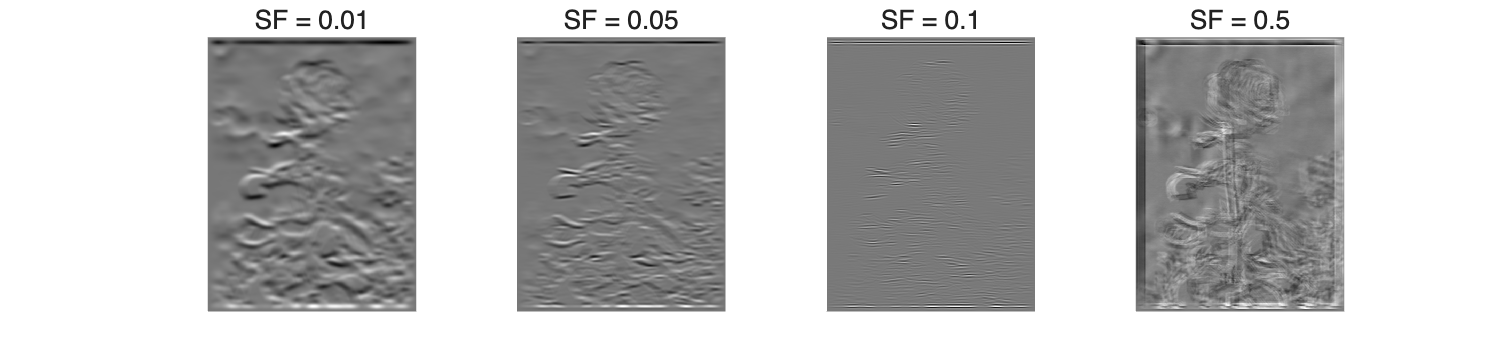

% sigma_x = 3; % standard deviation in x-direction
% sigma_y = 25; % standard deviation in y-direction
SFs = [0.01, 0.05, 0.1, 0.5];
titles = {'0.01', '0.05', '0.1', '0.5'};
OR = pi/2;
X = x*cos(OR) + y*sin(OR);
Y = -x*sin(OR) + y*cos(OR);
figure('Position', [100, 100, 1500, 350]);
for i = 1:4
    SF = SFs(i);
    gaussian_2d = 1/(2*pi*sigma_x*sigma_y) * exp(-(X.^2/(2*sigma_x^2)+Y.^2/(2*sigma_y^2)));
    A = sin(2*pi*SF*X);
    Gabor_function = A .* gaussian_2d;

    img_conv = conv2(img, Gabor_function);

    subplot(1,4,i)
    imagesc(img_conv);
    colormap(gray);
    axis image;
    axis off;
    title(['SF = ' titles{i}]);
end

## This project demonstrated that V1 simple cells encode an image by breaking it into features of various orientation and scale, letting the brain extract both edges and textures from the visual scene.